# **3. External space disturbances simulation**

clear; clc
%%ANIMATION FLAG
animationsGraphs = false;

## **0. Projected Areas Algorithm**

The proposed algorithm calculates the effective area ($A_{efec}$) over the main axis of a polyhedron oriented by a quaternion ($q$) when exposed to an incident vector ($v$). The proposed algorithm is defined as follows.

- Define the Incident Vector unitary direction $d = \frac{v}{||v||}$.

- Define the $N$ areas vectors which represent the unitary direction vectors of the polyhedron’s faces ($A_i$) where $i = 1,2,3,...N. $ And the area values are denoted as $S_i$ for each $i$-th value.

- Rotate $A_i$ according to $q$ quaternion: $rotA_i = rot(q, A_i)$.

- The Projection of the $i - th$  Rotated Face onto the Incident Vector ($d$) can be calculated with the dot product.

                
$$A_{efec} = \sum_{i=1}^N  S_i \cdot rotA_i \cdot f (rotA_i \cdot d)$$


        Where $f$ is defined as:


$$f\left(x\right)=\left\lbrace \begin{array}{ll}
x & \textrm{if}\;x>0\\
0 & \textrm{if}\;x\le 0
\end{array}\right.$$


The following code shows the implementation of the proposed algorithm for a paraleliped.

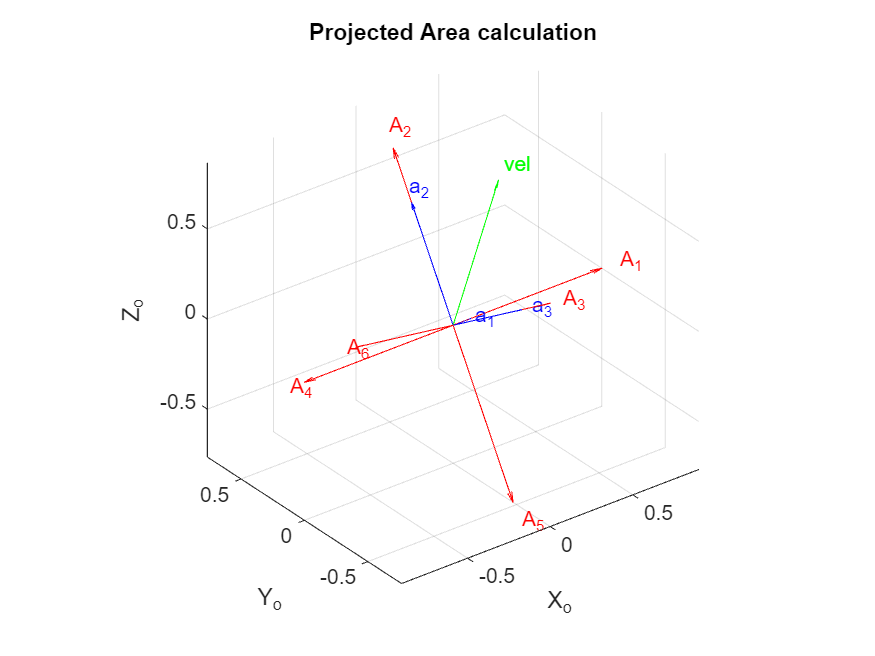

Aefec = efectiveArea([1,-2,8]',1,eul2quat([0,0,45])','true'); 
title('Projected Area calculation'); 
xlabel('X_o'); ylabel('Y_o'); zlabel('Z_o');

disp(Aefec);

    0.1204
   -0.2408
    0.9631



## **1. SPACE DISTURBANCES **

Spacecrafts are subjected to variable disturbances resulting from the various properties of the low earth orbit (LEO) environment. Approximated simple models are used for preliminary analysis. In the following part, we will present the most common disturbances of a circular orbit. The worst-case condition for each case will serve as the basis for the design of the ADCS.

The disturbances that act on LEO spacecraft emerge from: 

- The gravity gradient.

- The geomagnetic field and its interaction with residual spacecraft dipoles.

- The solar pressure.

- The aerodynamical interaction with the rarefied gas environment in earth orbit.

### **1.2. Gravity Gradient**

The external torques that affect a Satellite are various. However, for low orbit satellites, the major disturbance that a CubeSat is exposed to is the gravity gradient torque $L_ {gg}$ which is defined in [1] and [2] as (1.2.1).

$L=L_{gg}=3\omega_o^2c_3\times I_Bc_3$       (1.2.1)

And $\omega_o$ and $c_3$ is defined in (1.2.2) and (1.2.3) respectively.

$\omega_o^2=\frac{\mu}{r_c^3}$  (1.2.2)

$c_3 =C\left(q\right)\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\left(q_1 q_3 -q_2 q_4 \right)\;\\
2\left(q_2 q_3 -q_1 q_4 \right)\\
1-2\left(q_1^2 -q_2^2 \right)
\end{array}\right\rbrack$ (1.2.3)

Where:

- $\mu$: Earth’s gravitational coefficient ($\mu=3.986\times10^{14}$).

- $r_c^3$: Distance from the center of earth.

- $C(q)$: Attitude Matrix.

- $c_3$: Nadir-pointing unit vector.

The following Code shows a function that implements the gravity gradient disturbance

### **1.3** **Solar Radiation Pressure (SRP)**

The pressure and the torque generated by the radiation emitted by the sun are governed by the solar constant. It is defined as the normal energy flux onto a unit area per unit time, outside of the atmosphere, at one astronomical unit (1 AU = average earth-sun distance). The solar constant has an uncertainty of about ±10 W/m2. The normal values for the electromagnetic radiation of the sun are as follows:

- Solar constant at 1 AU 1371 W/m2

- Max. solar energy flux (European winter) 1428 W/m2

- Min. solar energy flux (European summer) 1316 W/m2

The resulting torque follows the equation (2.71). 

$T_{sp} =\frac{S_0 }{c}\ldotp A\ldotp {\left(1+q\right)}\ldotp \cos {\left(i\right)}\ldotp {\left(c_{ps} -c_g \right)}$    (2.71)

With

- $S_0$: Solar constant [W/m²] = 1428 W/m² (max)

- $c$ : Speed of light [m/s] = 3*10^8 m/s

- $A$: Projected Area [m²]

- $q$: Reflectance factor (0: perfectly absorbing, 1: perfectly reflecting)

- $i$: Angle of incidence [rad]

- $cps-cg$: Distance between center of pressure and center of gravity [m]

The program is calculated in the following code

### 1.4. Atmospheric Drag

To calculate the aerodynamic drag acting on the satellite, first is necessary to model the density as a function of latitude which is described as (2.72). 

    $\rho =\rho_0 e^{\frac{h_0 -h}{H}}$ (2.72)

Where:

- $\rho$: is the density at a specific altitude [kg/m³]

- $h$: is the specific altitude [km]

- $\rho_0$: is the reference density [kg/m³]

- $h_0$: is the reference altitude [km]

- $H$: is the scale altitude [km]

The model for the torque due to aerodynamic effects is described by (2.73).

$T_a =\frac{1}{2}\rho c_D Av_c^2 {\left(c_{pa} -c_g \right)}$    (2.73)

 Where:

- $\rho$ is the density [kg/$m^3$]

- $c_D$ is the coefficient of drag (usually between 2 and 2.5).

- $A$ is the projected Area [$m^2$]

- $v_C$ is the orbital velocity [m/s].

- $c_{pa} - c_g$ is the distance between center of pressure and center of gravity [m].

 The following code presents an implementation of the Aerodynamic drag.

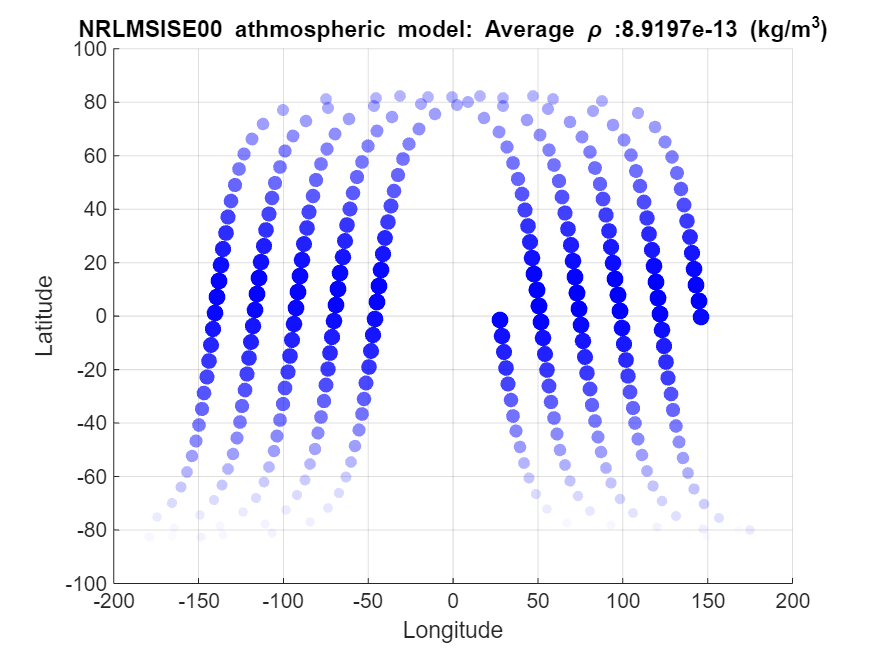

atm = struct('d',zeros(9,1),'t',zeros(2)); 
ap_a = struct('a',zeros(7,1));
input = struct('year',0,'doy',0,'sec',0,'alt',0,'g_lat',0,'g_long',0,'lst',0,'f107A',0,'f107',0,'ap',0,'ap_a',ap_a);

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;                                %% Planet Radius (meters)
earth.Mass         = 5.972E24;                              %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;                             %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;         %% G*M product (Nm^2/kg)

%% Orbit Parameters
%%%Orbital parameters
orbit.altitude    = 500E3;   
orbit.semiMajorAxis = orbit.altitude+earth.Radius;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0;
orbit.period      = 2*pi/sqrt(earth.mu)*orbit.semiMajorAxis^(3/2); % Orbital period
orbit.vcircular   = sqrt(earth.mu/orbit.semiMajorAxis);            % Circular velocity

%%% Setting Time Window (just 5 orbit)
settings.startTime = datetime(2023,08,30,12,35,38);
settings.sampleTime = 120;
settings.number_of_orbits = 5;
settings.tfinal = orbit.period*settings.number_of_orbits;
settings.stopTime = settings.startTime  + seconds(orbit.period*settings.number_of_orbits);

%% Create satellite scenario to use SPG4 propagator
sc = satelliteScenario(settings.startTime ,settings.stopTime,settings.sampleTime);
sat.satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

tarr = linspace(settings.startTime,settings.stopTime,300);

for i = 1:length(tarr)
    datetime_t = tarr(i);
    [positionGCRF, velGCRF] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
    [input(i),atm(i)] = callNRLsise00(positionGCRF, datetime_t);
end

figure()
averageRho = 0;
for i = 1:length(tarr)
    %geoplot(input(i).g_lat,input(i).g_long,'r.','LineWidth',1);hold on;
    scatter(input(i).g_long, input(i).g_lat, atm(i).d(6)*5e13,'filled',...
        'AlphaData',atm(i).d(6)*3e13, 'MarkerFaceColor', 'blue','MarkerFaceAlpha','flat');
    averageRho = averageRho+atm(i).d(6);
    hold on;
end
averageRho=averageRho/length(tarr);
title(['NRLMSISE00 athmospheric model: Average \rho :', num2str(averageRho),' (kg/m^3)']);
xlabel('Longitude'); ylabel('Latitude'); grid on;

### 1.5. Geomagnetic interaction

The spacecraft's motion across the geomagnetic field induces an electromagnetic field in the spacecraft, which in return interacts with the geomagnetic field, generating a disturbance torque that can be expressed by (2.74). 

    ${\overset{-}{T} }_m =\overset{-}{D} x\overset{-}{B}$       (2.74)

  With:

- D: is residual magnetic dipole vector.

- B: is local geomagnetic field vector.

In the worst possible case, the vectors are perpendicular to each other, and the worst moment is described as (2.75). 

    $T_m =D\frac{2M}{R^3 }$ (2.75)

## 1.3. Satellite Simulations (Ideal Case)

#### 1.3.1 Satellite Dynamics

We use the rotational Dynamics equation


$$\dot{\omega} = [I]^{-1} [T_c+T_d - \omega \times ([I] \omega)]$$


- $I$: Satellite Inertia tensor.

- $T_c$: Torque Controll

- $T_d$: Disturbances torque (Gravity Gradient)

- $\omega$: Angular rate 

The translation Dynamics


$$\ddot{x} = \frac{F_g}{m} + a_{pert}$$


- $F_g$: Gravitational Force.

- m: Satellite mass.

- $a_{pert}$: Disturbances

- $x$: Satellite position.


$$F_g = \frac{-GMm}{|x|^2}\frac{x}{|x|}$$


- $G$: Gravitational constant 6.668E-11 m^3 / kg - s^2

- M: Earth mass.

- m: Satellite mass

- x: satellite positiom

Kinematic equation in quaternions


$$\dot q = \frac{1}{2}\Xi(q)$$


Where $\Xi(q)$ is described by equation (1.3.2).


$$\Xi \left(q\right)=\left\lbrack \begin{array}{ccc}
q_4  & -q_3  & q_2 \\
q_3  & q_4  & -q_1 \\
-q_2  & q_1  & q_4 \\
-q_1  & -q_2  & -q_3 
\end{array}\right\rbrack$$


**1.3.3. Satellite Parameters**

Clear and errase variables.

%%% Clear previous variables
clearvars -except animationsGraphs
clear persistent
clear global
clc

- **Satellite inertia**

%%%Inertia tens
sat.Is = [0.103682,-0.001094, 0.015519;...
         -0.001094, 0.104158,-2.570e-6;...
          0.015519, 2.570e-6, 0.088588];
sat.mass = 40; %Kg
sat.projArea = 30E-3*30E-3;               %m^2
sat.reflection = 1-0.38;                  %Considering al surfaces with Aluminum 6061-T6
sat.cps_cg = -5E-2 + (2*5E-2).*rand(1,3); %random displacement up to 5cm. (m)

- **Earth Parameters**

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;                                %% Planet Radius (meters)
earth.Mass         = 5.972E24;                              %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;                             %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;         %% G*M product (Nm^2/kg)

- **Orbit Parameters**

%% Orbit Parameters
%%%Orbital parameters
orbit.altitude    = 500E3;                                      % Meters
orbit.inclination = deg2rad(97.4);                              % SSO inclination (rad)
orbit.semi_major  = orbit.altitude+earth.Radius;                % Semi_major calculated knowing e = cero
orbit.period      = 2*pi/sqrt(earth.mu)*orbit.semi_major^(3/2); % Orbital period
orbit.vcircular   = sqrt(earth.mu/orbit.semi_major);            % Circular velocity

- **Satellite Disturbances**

%%% External disturbances
disturbance = @(state) dist_gravityGrad(state,sat,orbit,earth);
%disturbance2 = @(state) dist_gravityGrad(state,sat,orbit,earth);

- **Initial conditions**

%% Initial Conditions
%%% Initial position in the fixed inertial frame (x,y,z)
initial.X.x0 = earth.Radius + orbit.altitude;     % Initial position x
initial.X.y0 = 0;                                 % Initial position y
initial.X.z0 = 0;                                 % Initial position z
%%%Calculate initial displacement rates
initial.Xdot.xdot0 = 0;
initial.Xdot.ydot0 = orbit.vcircular*cos(orbit.inclination);
initial.Xdot.zdot0 = orbit.vcircular*sin(orbit.inclination);
%%% Intitial Conditions for Attitude and Angular Velocity (Euler angles)
initial.atitude.rpy0_deg(1)    = 0;           %  Initial Roll  (deg)
initial.atitude.rpy0_deg(2)    = 0;           %  Initial Pitch (deg)
initial.atitude.rpy0_deg(3)    = 0;           %  Initial Yaw   (deg)
%%% Initial Euler Angles and quaternions
initial.atitude.rpy0_rad    = deg2rad([initial.atitude.rpy0_deg(1),...
    initial.atitude.rpy0_deg(2),...
    initial.atitude.rpy0_deg(3)]');       % Euler Angles (rad)
initial.atitude.q0123_0 = EulerAngles2Quaternions(initial.atitude.rpy0_rad);  % Quaternions
%%% Initial angular rates in the body frame (rad/s)
initial.omega.omega0_x = 0.0;
initial.omega.omega0_y = 0.0;
initial.omega.omega0_z = 0.0;

#### 1.3.4. Start Satellite Simulation (IDEAL CASE)

%%% Global variables
global varNames curValues varValues
varNames = {'Td'};
curValues = struct(); varValues = struct();

- **Simulation Settings**

%% Simulation Parameters
%%% Setting Time Window (just 5 orbit)
settings.number_of_orbits = 5;
settings.tfinal = orbit.period*settings.number_of_orbits;
%%% Satellite initial states
settings.X0 = [initial.X.x0;            initial.X.y0;        initial.X.z0; ...
    initial.Xdot.xdot0; initial.Xdot.ydot0; initial.Xdot.zdot0; ...
    initial.atitude.q0123_0;            initial.omega.omega0_x; ...
    initial.omega.omega0_y ;            initial.omega.omega0_z];

- **Simulation **

%% Solve by variable step Runge Kutta of 4 order
tic
opts = odeset('InitialStep',1e-4,'RelTol',1e-6,'Events', @(t, x) store_var(t, x));
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'GWSAT-1 Simulation Progress');
[tout,x] = ode45(@(t,x) satelliteSim(t, x, sat, earth, disturbance, settings),...
    [0 settings.tfinal],settings.X0,opts);

The following variables are recording.
    {'Td'}



elapsedTime = toc;

%%%Recover disturbances
dis_v = zeros(3,length(x));
for i = 1:length(x)
    dis_v(:,i) = disturbance(x(i,:));
end
% Print the elapsed time in seconds
fprintf('Elapsed time: %.3f miliseconds\n',elapsedTime*1000);

Elapsed time: 11982.943 miliseconds


#### **1.3.5. Plot Simulation**

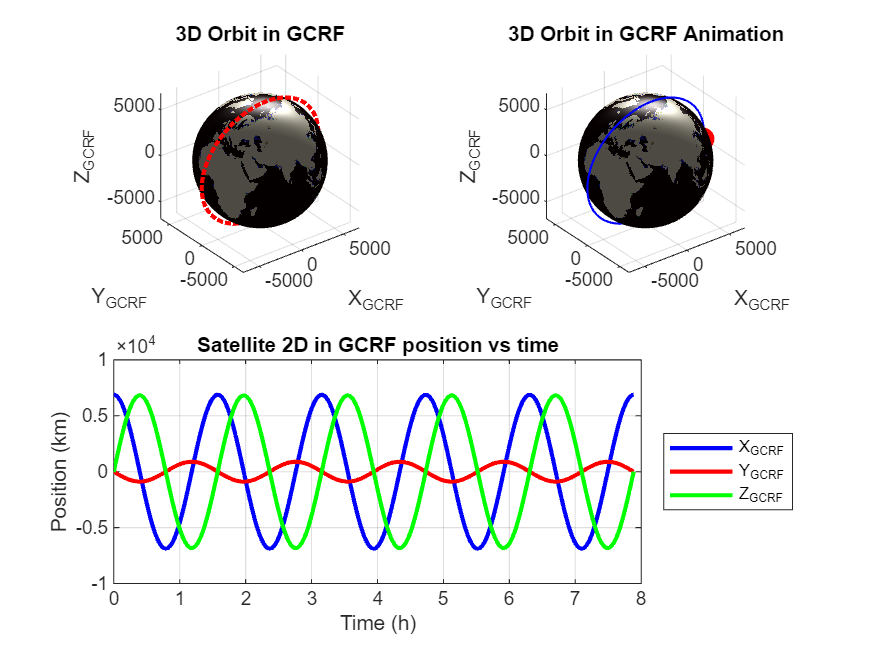

%% Rename index
xyzout =   x(:,1:3);                            %%Satellite position(m)
q0123out = x(:,7:10);                           %%Satellite quaternions
ptpout = Quaternions2EulerAngles(q0123out);     %%Satellite euler angles
pqrout = x(:,11:13);                            %%Angular Rates

%%%Build Earth
load('topo.mat', 'topo', 'topomap1');           %%Load earth elevation data
[rows, cols] = size(topo);                      %%Obtain elevation data size
[X, Y, Z] = sphere(rows-1, cols-1);             %%Create 3D earth sphere
X = X*earth.Radius/1000; Y = Y*earth.Radius/1000; Z = Z*earth.Radius/1000;
    
figure();
%%%Plot 2D position in GCRF
subplot(2,1,2);
    plot(tout/3600,xyzout(:,1)/1E3,'b-','LineWidth',2); hold on; grid on;
    plot(tout/3600,xyzout(:,2)/1E3,'r-','LineWidth',2);
    plot(tout/3600,xyzout(:,3)/1E3,'g-','LineWidth',2);
    xlabel('Time (h)'); ylabel('Position (km)');
    legend('X_{GCRF}','Y_{GCRF}','Z_{GCRF}','Location','eastoutside');
    title('Satellite 2D in GCRF position vs time');
%% Plot 3D position in GCRF
subplot(2,2,1)
    %%%Draw earth in Km and satellite orbit
    plot3(xyzout(:,1)/1000,xyzout(:,2)/1000,xyzout(:,3)/1000,'r:','LineWidth',2);
    xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}'); grid on; hold on;
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
    colormap(topomap1); axis equal; 
    %%%Set view and ilumination
    light('Position', [1 1 1]); lighting gouraud; view(3);
    %%%Add title
    title('3D Orbit in GCRF')
    
% Draw earth in Km and satellite orbit
subplot(2,2,2);
    h1 = plot3(xyzout(1,1)/1000,xyzout(1,2)/1000,xyzout(1,3)/1000,'ro','LineWidth',5); hold on; %#ok
    plot3(xyzout(:,1)/1000,xyzout(:,2)/1000,xyzout(:,3)/1000,'b:','LineWidth',1);
    xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
    grid on; hold on;
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
    colormap(topomap1);
    axis equal
    % Set view and ilumination
    light('Position', [1 1 1]);
    lighting gouraud;
    view(3);
    % Add title
    title('3D Orbit in GCRF Animation')

    if animationsGraphs
        for i = 1:length(x) %#ok
            set(h1, 'XData', xyzout(i,1)/1000, 'YData', xyzout(i,2)/1000, 'ZData',xyzout(i,3)/1000);
            pause(0.01);
        end
    end
 

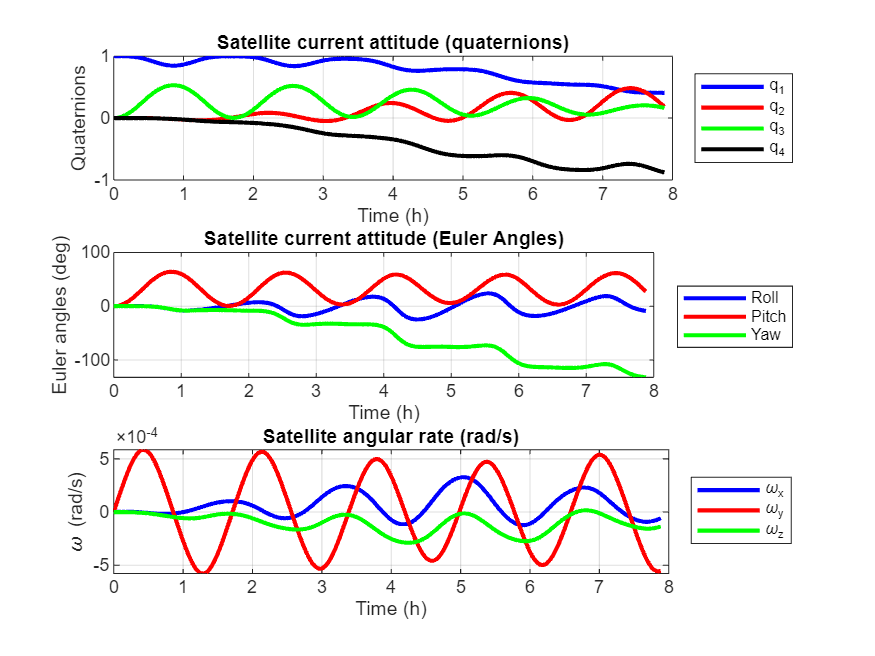

figure();
subplot(3,1,1)
h1 = plot(tout/3600,q0123out(:,1),'b-','LineWidth',2);
hold on
grid on
h2 = plot(tout/3600,q0123out(:,2),'r-','LineWidth',2);
h3 = plot(tout/3600,q0123out(:,3),'g-','LineWidth',2);
h4 = plot(tout/3600,q0123out(:,4),'k-','LineWidth',2);
xlabel('Time (h)');
ylabel('Quaternions');
legend([h1,h2,h3,h4],'q_1','q_2','q_3','q_4','Location','eastoutside');
title('Satellite current attitude (quaternions)');

subplot(3,1,2)
h1 = plot(tout/3600,rad2deg(ptpout(:,1)),'b-','LineWidth',2);
hold on
grid on
h2 = plot(tout/3600,rad2deg(ptpout(:,2)),'r-','LineWidth',2);
h3 = plot(tout/3600,rad2deg(ptpout(:,3)),'g-','LineWidth',2);
xlabel('Time (h)');
ylabel('Euler angles (deg)');
legend([h1,h2,h3],'Roll','Pitch','Yaw','Location','eastoutside');
title('Satellite current attitude (Euler Angles)');
subplot(3,1,3)
h1 = plot(tout/3600,pqrout(:,1),'b-','LineWidth',2);
hold on
grid on
h2 = plot(tout/3600,pqrout(:,2),'r-','LineWidth',2);
h3 = plot(tout/3600,pqrout(:,3),'g-','LineWidth',2);
xlabel('Time (h)');
ylabel('\omega (rad/s)');
legend([h1,h2,h3],'\omega_x','\omega_y','\omega_z','Location','eastoutside');
title('Satellite angular rate (rad/s)');

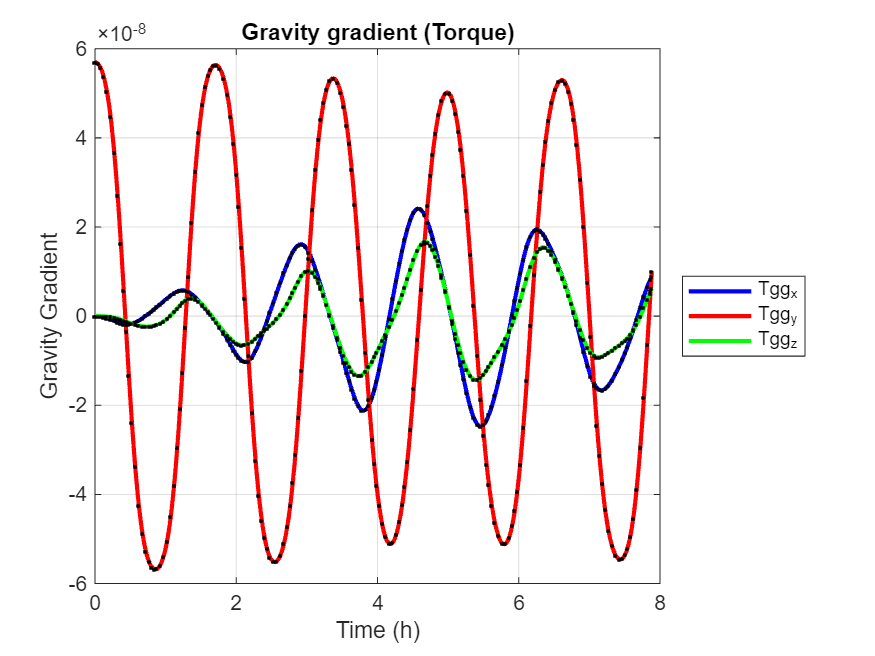

figure();
h1 = plot(tout/3600,dis_v(1,:),'b-','LineWidth',2);
hold on; grid on;
h2 = plot(tout/3600,dis_v(2,:),'r-','LineWidth',2);
h3 = plot(tout/3600,dis_v(3,:),'g-','LineWidth',2);
p = plot(varValues.time/3600,varValues.Td,'k.','MarkerSize',5);
xlabel('Time (h)');
ylabel('Gravity Gradient');
legend([h1,h2,h3],'Tgg_x','Tgg_y','Tgg_z','Location','eastoutside');
title('Gravity gradient (Torque)');

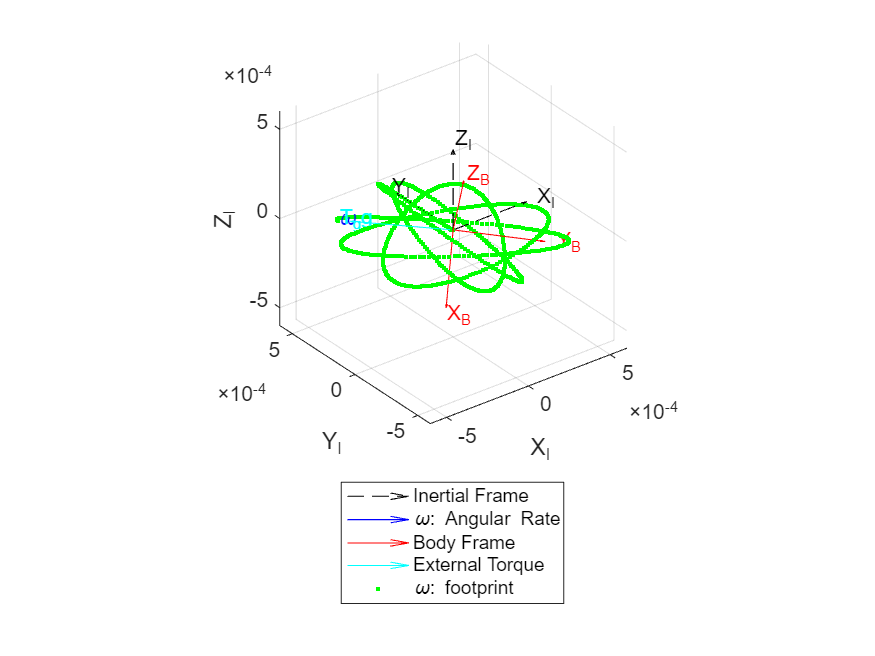

figure()
%%Plot settings
scaleFrames = 5E-4; scaleAngRate = 1; scaleTgg = 1;

%% Rename index
q0123out = x(:,7:10);       %%Satellite quaternions
pqrout = x(:,11:13);        %%Angular Rates

%%% Plot inertia frame I
[h1,~] = plotVector(zeros(1,3), [1,0,0], scaleFrames, 'k--', 'X_I', 'e'); hold on
plotVector(zeros(1,3), [0,1,0], scaleFrames, 'k--', 'Y_I', 'e');
plotVector(zeros(1,3), [0,0,1], scaleFrames, 'k--', 'Z_I', 'e');
plotPoint (zeros(1,3), 'k.', 'O_I', -0.08);

%%% Allocate variables
%wout_i_V = struct();
wout_i_V = zeros(3,length(x));
ri_v     = struct();
tgg_v    = struct();

for i = 1:length(x)
        %Calculate rotation Matrix arround u axis
        axisx = quatRotation(q0123out(i,:)',[1,0,0]');
        axisy = quatRotation(q0123out(i,:)',[0,1,0]');
        axisz = quatRotation(q0123out(i,:)',[0,0,1]');
        ri_v.(['n_',num2str(i)]) = [axisx',axisy',axisz'];
        %Calculate rotated angular rate
        wout_i = quatRotation(q0123out(i,:)',pqrout(i,:)');
        wout_i_V(:,i) = wout_i';
        %Calculate rotated rate
        tgg_i = quatRotation(q0123out(i,:)',pqrout(i,:)');
        tgg_v.(['n_',num2str(i)]) = tgg_i';
end

if animationsGraphs
    %%% Plot angular rate
    [h2,  h3]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',pqrout(1,:)') ,scaleAngRate,'b-','\omega','e');%#ok
    
    %%% Plot Body Frame
    [h4,  h5]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',[1,0,0]'),scaleFrames, 'r-', 'X_B', 'e');
    [h6,  h7]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',[0,1,0]'),scaleFrames, 'r-', 'Y_B', 'e');
    [h8,  h9]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',[0,0,1]'),scaleFrames, 'r-', 'Z_B', 'e');
        
    %%% Plot External torque
    [h10,  h11]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)', dis_v(:,1)),scaleTgg, 'c-', 'T_gg', 'e');
    xlim([-6E-4 6E-4]); ylim([-6E-4 6E-4]); zlim([-6E-4 6E-4]);
    xlabel('X_I'); ylabel('Y_I'); zlabel('Z_I');

    for i =  1:length(x)
        Wb  = wout_i_V(:,i)*scaleAngRate;
        B   = ri_v.(['n_',num2str(i)])*scaleFrames;
        tgg = tgg_v.(['n_',num2str(i)])*scaleTgg;
        
        h12 = plot3(Wb(1),Wb(2),Wb(3),'g.');
        
        set(h2, 'UData', Wb(1), 'VData', Wb(2), 'WData', Wb(3));
        set(h3, 'Position', Wb);
        
        set(h4, 'UData', B(1,1), 'VData', B(2,1), 'WData', B(3,1));      
        set(h5, 'Position', B(:,1));
        
        set(h6, 'UData', B(1,2), 'VData', B(2,2), 'WData', B(3,2));      
        set(h7, 'Position', B(:,2));
        
        set(h8, 'UData', B(1,3), 'VData', B(2,3), 'WData', B(3,3));      
        set(h9, 'Position', B(:,3));
        
        set(h10, 'UData', tgg(1), 'VData', tgg(2), 'WData', tgg(3));
        set(h11, 'Position', tgg);
        
        %%% Pause animation
        pause(0.01);
    end
else
    %%% Plot angular rate
    [h2,  ~]  = plotVector(zeros(1,3), quatRotation(q0123out(end,:)',pqrout(end,:)') ,scaleAngRate,'b-','\omega','e');
    
    %%% Plot Body Frame
    [h4,  h5]  = plotVector(zeros(1,3), quatRotation(q0123out(end,:)',[1,0,0]'),scaleFrames, 'r-', 'X_B', 'e');
    [h6,  h7]  = plotVector(zeros(1,3), quatRotation(q0123out(end,:)',[0,1,0]'),scaleFrames, 'r-', 'Y_B', 'e');
    [h8,  h9]  = plotVector(zeros(1,3), quatRotation(q0123out(end,:)',[0,0,1]'),scaleFrames, 'r-', 'Z_B', 'e');
    
    %%% Plot footprint
    h12 = plot3(wout_i_V(1,:),wout_i_V(2,:),wout_i_V(3,:),'g.');
    
    %%% Plot External torque
    [h10,  h11]  = plotVector(zeros(1,3), tgg_v.(['n_',num2str(length(x))]),1, 'c-', 'T_gg', 'e');
    xlim([-6E-4 6E-4]); ylim([-6E-4 6E-4]); zlim([-6E-4 6E-4]);
    xlabel('X_I'); ylabel('Y_I'); zlabel('Z_I');
end
legend([h1,h2,h4,h10,h12],'Inertial Frame','\omega: Angular Rate','Body Frame','External Torque','\omega: footprint','Location','southoutside')

#### 1.3.5. Start Satellite Simulation (With SPG4 propagator)

**1.3.3. Satellite Parameters**

Clear and errase variables.

%%% Clear previous variables
clearvars -except animationsGraphs
clear persistent
clear global
clc

- **Satellite inertia**

%%%Inertia tens
sat.Is = [0.103682,-0.001094, 0.015519;...
         -0.001094, 0.104158,-2.570e-6;...
          0.015519, 2.570e-6, 0.088588];
sat.mass = 40;         % Kg
sat.side = 300E-3;     % m
sat.Area = sat.side^2; % m^2
sat.reflection = 1-0.38;                  %Considering al surfaces with Aluminum 6061-T6
sat.cps_cg = -5E-2 + (2*5E-2).*rand(3,1); %random displacement up to 5cm. (m)
sat.cd = 2 + (2.5-2).*rand(1,1);          %between 2 and 2.5
sat.cpa_cg = -5E-2 + (2*5E-2).*rand(3,1); %random displacement up to 5cm. (m) 

- **Earth Parameters**

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;               %% Planet Radius (meters)
earth.Mass         = 5.972E24;             %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;            %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;        %% G*M product (Nm^2/kg)

- **Orbit Parameters**

%% Orbit Parameters
%%%Orbital parameters
orbit.altitude    = 500E3;   
orbit.semiMajorAxis = orbit.altitude+earth.Radius;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0;
orbit.period      = 2*pi/sqrt(earth.mu)*orbit.semiMajorAxis^(3/2); % Orbital period
orbit.vcircular   = sqrt(earth.mu/orbit.semiMajorAxis);            % Circular velocity
orbit.atmdensity  = 8.916705319842712e-13;                         % Average density calculated by NRLMSISE00

- **Satellite Disturbances**

%%% External diisturbances
disturbance1 = @(state) dist_gravityGrad(state,sat,orbit,earth);
disturbance2 = @(projA) dist_solRad(projA,sat);
disturbance3 = @(projA,vel) dist_aeroDrag(projA, vel, orbit.atmdensity, sat);

- **Initial conditions**

%% Initial Conditions
%%% Intitial Conditions for Attitude and Angular Velocity (Euler angles)
initial.atitude.rpy0_deg(1)    = 0;           %  Initial Roll  (deg)
initial.atitude.rpy0_deg(2)    = 0;           %  Initial Pitch (deg)
initial.atitude.rpy0_deg(3)    = 0;           %  Initial Yaw   (deg)
%%% Initial Euler Angles and quaternions
initial.atitude.rpy0_rad    = deg2rad([initial.atitude.rpy0_deg(1),...
    initial.atitude.rpy0_deg(2),...
    initial.atitude.rpy0_deg(3)]');       % Euler Angles (rad)
initial.atitude.q0123_0 = EulerAngles2Quaternions(initial.atitude.rpy0_rad);  % Quaternions
%%% Initial angular rates in the body frame (rad/s)
initial.omega.omega0_x = 0.0;
initial.omega.omega0_y = 0.0;
initial.omega.omega0_z = 0.0;

#### 1.3.4. Start Satellite Simulation (SPG4 propagator)

- **Simulation Settings**

%% Simulation Parameters
%%% Setting Time Window (just 5 orbit)
settings.startTime = datetime(2023,08,30,12,35,38);
settings.sampleTime = 500;
settings.number_of_orbits = 100;
settings.tfinal = orbit.period*settings.number_of_orbits;
settings.stopTime = settings.startTime  + seconds(orbit.period*settings.number_of_orbits);

%%% Satellite initial states
settings.X0 = [initial.atitude.q0123_0; initial.omega.omega0_x; ...
               initial.omega.omega0_y ; initial.omega.omega0_z];

%% Create satellite scenario to use SPG4 propagator
sc = satelliteScenario(settings.startTime ,settings.stopTime,settings.sampleTime);
sat.satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

- **Simulation **

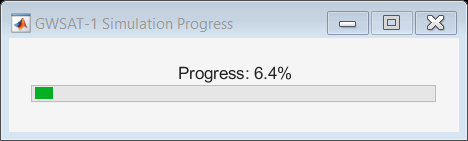

%% Solve by variable step Runge Kutta of 4 order and use SPG4 propagator 
tic
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'GWSAT-1 Simulation Progress');
% Función de eventos para almacenar u(t) en cada paso
opts = odeset('InitialStep',1e-4,'RelTol',1e-6);
[tout,x] = ode45(@(t,x) satelliteSPG4sim(t, x, sat, disturbance1, disturbance2, disturbance3,... 
    settings),[0 settings.tfinal],settings.X0,opts);

elapsedTime = toc;

%%%Recover disturbances
%%%Allocate variables
dis_tgg   = zeros(3,length(x));
sun_avail = zeros(1,length(x));
dis_solar = zeros(3,length(x));
dis_drag  = zeros(3,length(x));
totaltorque = zeros(3,length(x));
normTtorque = zeros(1,length(x));
xyzout = zeros(3,length(x));
for i = 1:length(x)
    %%%Recover time
    datetime_t  = settings.startTime  + seconds(tout(i));
    %%%Recover Position
    [positionGCRF, velGCRF] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
    %%% Get sun position 
    [sun_i,r_sun] = solar(datetime_t.Year,datetime_t.Month,datetime_t.Day,datetime_t.Hour,datetime_t.Minute,datetime_t.Second);
    %%%Determine eclipse condition
    sun_avail(i) = eclipse(positionGCRF*1e-3,r_sun*1e-3*sun_i);
    %%% Get rotation matrix from orbit to inertia
    oX=getUnitVector(velGCRF); oZ=-1*getUnitVector(positionGCRF); oY=cross(oZ,oX);
    rot_orbit_I=horzcat(oX,oY,oZ);

    %%% Get distubance
    dis_tgg(:,i)   = disturbance1([zeros(1,6),x(i,:)]);

    %%% Get drag disturbance
    AefecDrag = efectiveArea(quatRotation(quatconj(x(i,1:4)),[1,0,0]),sat.Area,[1,0,0,0],false);
    dis_drag(:,i) = disturbance3(AefecDrag,velGCRF);

    %%% Get solar disturbance
    if sun_avail(i) == 1
        sun_orbit = rot_orbit_I'*sun_i';
        %Aefec = efectiveArea(sun_orbit,sat.Area,x(i,1:4),false);
        Aefecb = efectiveArea(quatRotation(quatconj(x(i,1:4)),sun_orbit),sat.Area,[1,0,0,0],false);
        dis_solar(:,i) = disturbance2(Aefecb);
    else
        dis_solar(:,i) = zeros(3, 1);
    end
    totaltorque(:,i) = dis_tgg(:,i)+dis_drag(:,i)+dis_solar(:,i);
    normTtorque(i) = norm(totaltorque(:,i));
    xyzout(:,i) = states(sat.satSGP4,datetime_t,"CoordinateFrame", "ecef");
end
%totaltorque = dis_tgg+dis_drag+dis_solar;
% Print the elapsed time in seconds
fprintf('Elapsed time: %.3f miliseconds\n',elapsedTime*1000);

If simulation is already runing, just recover its results

% fileName = {'sat_param.mat','sat_positions.mat','sat_states.mat','sat_times.mat',...
%     'sunAvailable.mat','tdrag.mat','tgg.mat','tnorm.mat','tsolar.mat','tTotal.mat'};
% for i = 1:length(fileName)
%     load(fileName{1,i});
% end

Plot new figures with the new project

%% Rename index
q0123out = x(:,1:4);                           %%Satellite quaternions
ptpout = Quaternions2EulerAngles(q0123out);    %%Satellite euler angles
pqrout = x(:,5:7);                             %%Angular Rates

%% Plot 2D position
%%%Plot satellite position as a function of time
figure();
    subplot(2,1,2);
    plot(tout/3600,xyzout(1,:)/1E3,'b-','LineWidth',2); hold on; grid on;
    plot(tout/3600,xyzout(2,:)/1E3,'r-','LineWidth',2);
    plot(tout/3600,xyzout(3,:)/1E3,'g-','LineWidth',2);
    xlabel('Time (h)'); ylabel('Position (km)');
    legend('X_{GCRF}','Y_{GCRF}','Z_{GCRF}','Location','eastoutside');
    title('Satellite 2D in GCRF position vs time');

%% Plot 3D position
subplot(2,2,1)
    %%%Build Earth
    %%%Load earth elevation data
    load('topo.mat', 'topo', 'topomap1');
    %%%Obtain elevation data size
    [rows, cols] = size(topo);
    %%%Create 3D earth sphere
    [X, Y, Z] = sphere(rows-1, cols-1);
    X = X*earth.Radius/1000;
    Y = Y*earth.Radius/1000;
    Z = Z*earth.Radius/1000;
    %%%Draw earth in Km and satellite orbit
    h0 = plot3(xyzout(1,:)/1000,xyzout(2,:)/1000,xyzout(3,:)/1000,'r:','LineWidth',2);
    xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}')
    grid on
    hold on
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
    %legend(h0,'Satellite orbit (Km)','Location','southoutside');
    colormap(topomap1);
    axis equal
    %%%Set view and ilumination
    light('Position', [1 1 1]);
    lighting gouraud;
    view(3);
    %%%Add title
    title('3D Orbit in ECEF')
    
% Draw earth in Km and satellite orbit
subplot(2,2,2);
    h1 = plot3(xyzout(1,:)/1000,xyzout(2,:)/1000,xyzout(3,:)/1000,'ro','LineWidth',5);
    hold on;
    plot3(xyzout(1,:)/1000,xyzout(2,:)/1000,xyzout(3,:)/1000,'b:','LineWidth',1);
    xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
    grid on; hold on;
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
    colormap(topomap1);
    axis equal
    % Set view and ilumination
    light('Position', [1 1 1]);
    lighting gouraud;
    view(3);
    % Add title
    title('3D Orbit in ECEF Animation')

% for i = 1:length(x)
%     set(h1, 'XData', xyzout(1,i)/1000, 'YData', xyzout(2,i)/1000, 'ZData',xyzout(3,i)/1000);
%     pause(0.01);
% end

figure();
p1 = subplot(3,1,1);
h1 = plot(tout/3600,q0123out(:,1),'b.','LineWidth',0.1);
hold on;
grid on
h2 = plot(tout/3600,q0123out(:,2),'r.','LineWidth',0.1);
h3 = plot(tout/3600,q0123out(:,3),'g.','LineWidth',0.1);
h4 = plot(tout/3600,q0123out(:,4),'k.','LineWidth',0.1);
xlabel('Time (h)');
ylabel('Quaternions');
legend([h1,h2,h3,h4],'q_1','q_2','q_3','q_4','Location','eastoutside');
title('Satellite current attitude (quaternions)');

p2=subplot(3,1,2);
h1 = plot(tout/3600,rad2deg(ptpout(:,1)),'b.','LineWidth',0.1);
hold on
grid on
h2 = plot(tout/3600,rad2deg(ptpout(:,2)),'r.','LineWidth',0.1);
h3 = plot(tout/3600,rad2deg(ptpout(:,3)),'g.','LineWidth',0.1);
xlabel('Time (h)');
ylabel('Euler angles (deg)');
legend([h1,h2,h3],'Roll','Pitch','Yaw','Location','eastoutside');
title('Satellite current attitude (Euler Angles)');

p3=subplot(3,1,3);
h1 = plot(tout/3600,pqrout(:,1),'b.','LineWidth',0.1);
hold on
grid on
h2 = plot(tout/3600,pqrout(:,2),'r.','LineWidth',0.1);
h3 = plot(tout/3600,pqrout(:,3),'g.','LineWidth',0.1);
xlabel('Time (h)');
ylabel('\omega (rad/s)');
legend([h1,h2,h3],'\omega_x','\omega_y','\omega_z','Location','eastoutside');
title('Satellite angular rate (rad/s)');
linkaxes([p1,p2,p3],'x');

figure();
p1=subplot(3,1,1);
h1 = plot(tout/3600,dis_tgg(1,:),'b.','LineWidth',0.5);
hold on; grid on;
h2 = plot(tout/3600,dis_tgg(2,:),'r.','LineWidth',0.5);
h3 = plot(tout/3600,dis_tgg(3,:),'g.','LineWidth',0.5);
xlabel('Time (h)');
ylabel('Gravity Gradient Torque (N.m)');
legend([h1,h2,h3],['Tgg_x, Max: ', num2str(max(dis_tgg(1,:)),'%.2E'),'(N.m)'],...
                  ['Tgg_y, Max: ', num2str(max(dis_tgg(2,:)),'%.2E'),'(N.m)'],...
                  ['Tgg_z, Max: ', num2str(max(dis_tgg(3,:)),'%.2E'),'(N.m)'],'Location','eastoutside');
title('Gravity gradient (Torque)');

p2=subplot(3,1,2);
h1 = plot(tout/3600,dis_solar(1,:),'b.','LineWidth',0.5);
hold on; grid on;
h2 = plot(tout/3600,dis_solar(2,:),'r.','LineWidth',0.5);
h3 = plot(tout/3600,dis_solar(3,:),'g.','LineWidth',0.5);
xlabel('Time (h)');
ylabel('Solar pressure Torque (N.m)');
legend([h1,h2,h3],['Tx_{sun}, Max: ', num2str(max(dis_solar(1,:)),'%.2E'),'(N.m)'],...
                  ['Ty_{sun}, Max: ', num2str(max(dis_solar(2,:)),'%.2E'),'(N.m)'],...
                  ['Tz_{sun}, Max: ', num2str(max(dis_solar(3,:)),'%.2E'),'(N.m)'],'Location','eastoutside');
title('Solar Pressure (Torque)');

p3=subplot(3,1,3);
h1 = plot(tout/3600,dis_drag(1,:),'b.','LineWidth',0.5);
hold on; grid on;
h2 = plot(tout/3600,dis_drag(2,:),'r.','LineWidth',0.5);
h3 = plot(tout/3600,dis_drag(3,:),'g.','LineWidth',0.5);
xlabel('Time (h)');
ylabel('Aerodynamic Drag torque (N.m)');
legend([h1,h2,h3],['Tx_{drag}, Max: ', num2str(max(dis_drag(1,:)),'%.2E'),'(N.m)'],...
                  ['Ty_{drag}, Max: ', num2str(max(dis_drag(2,:)),'%.2E'),'(N.m)'],...
                  ['Tz_{drag}, Max: ', num2str(max(dis_drag(3,:)),'%.2E'),'(N.m)'],'Location','eastoutside');
title('Aerodynamic Drag torque');
linkaxes([p1,p2,p3],'x');

figure()
p1=subplot(2,1,1);
h1 = plot(tout/3600,totaltorque(1,:),'b.','LineWidth',0.5);
hold on; grid on;
h2 = plot(tout/3600,totaltorque(2,:),'r.','LineWidth',0.5);
h3 = plot(tout/3600,totaltorque(3,:),'g.','LineWidth',0.5);
xlabel('Time (h)');
ylabel('Disturbance Torque (N.m)');
legend([h1,h2,h3],['Tx, Max: ', num2str(max(totaltorque(1,:)),'%.2E'),'(N.m)'],...
                  ['Ty, Max: ', num2str(max(totaltorque(2,:)),'%.2E'),'(N.m)'],...
                  ['Tz, Max: ', num2str(max(totaltorque(3,:)),'%.2E'),'(N.m)'],'Location','eastoutside');
title(['GWSAT-1 Total Disturbance Simulation for ', num2str(round(tout(end)/3600)), ' h']);

p2=subplot(2,1,2);
envelope_signal = envelope(normTtorque,1E4,'peak');
h1 = plot(tout/3600,normTtorque,'r.','LineWidth',0.5);hold on;
h2 = plot(tout/3600,envelope_signal,'b--','LineWidth',2);
xlabel('Time (h)'); grid on;
ylabel('Total Torque Mag (N.m)');
legend([h1,h2],['||T||_2, Max: ', num2str(max(normTtorque),'%.2E'),'(N.m)'] ,'Envelope','Location','eastoutside');
title('Total torque Magnitude');
linkaxes([p1,p2],'x');

%%FFT analisys
[top_three_pks, top_three_freq, constant, t_uniform, x_uniform] = fftAalisys(90,tout,normTtorque);

sen1 = top_three_pks(1)*sin(2*pi*top_three_freq(1)*t_uniform);  % Función sinusoidal
sen2 = top_three_pks(2)*sin(2*pi*top_three_freq(2)*t_uniform);  % Función sinusoidal
sen3 = top_three_pks(3)*sin(2*pi*top_three_freq(3)*t_uniform);  % Función sinusoidal

peakSen1 = (max(normTtorque)-constant)*sin(2*pi*top_three_freq(1)*t_uniform);  % Función sinusoidal

figure()
h1 = plot(t_uniform/3600,x_uniform,'r-');hold on;grid on;
h2 = plot(t_uniform/3600,sen1+constant,'b-','LineWidth',2);
h3 = plot(t_uniform/3600,peakSen1+constant,'g-','LineWidth',2);
legend([h1,h2,h3],'Simulated Data','Main frequency component','Amplitude with safety margin');
xlabel('time (h)'); ylabel('Total Torque Mag (N.m)');title('Simplified Total torque Magnitude');

function [x_dot] = mySatellite(t, x, sat, earth , Td)%#ok
%%% Inputs
% t: current time
% x: satellite state
% sat: Satellite parameters
% earth: Earth parameters
% Td: External Disturbances

%%% Read state input
r   =  x(1:3);
vel =  x(4:6);
q   =  x(7:10);
w   =  x(11:13);

%% Read Satellite physical parameters
m  = sat.mass;
Is = sat.Is;

%%%Translational Dynamics
%%%Earth gravity Model
rho = norm(r);
rhat = r/rho;
Fgrav = -(earth.GravityConst*earth.Mass*m/rho^2)*rhat;
F = Fgrav;
accel = F/m;

%%%Rotational Dynamics
%%Book: Fundamentals of Spacecraft Attitude Determination and Control
%%Author: F. Landis Markley & John L. Crassidis
%%Quaternions Kinematics..Ecuación (2.88)
Xi=[-q(2),-q(3),-q(4);
    q(1),-q(4),q(3);
    q(4),q(1),-q(2);
    -q(3),q(2),q(1)];
q_dot=1/2*Xi*w;
%%%Kynematics Equation(3.21)
H = Is*w;                         %Satellite Angular momentun
w_dot = Is\(Td - cross(w,H));     %Dynamics Equatión (3.147)
%%%x_dot Vector
x_dot=[vel;accel;q_dot;w_dot];
end

function [x_dot] = satelliteSim(t, x, sat, earth, dist,settings)
%%%Global variables
global varNames curValues varValues
persistent availableVars
    
%% Disturbances
%LS2125204: Brayan Espinoza
%%% Get distubance
Td = dist(x);

%%% Satellite model
x_dot = mySatellite(t, x, sat, earth , Td);

%%% Progress bar configuration
%%%% Calculate the progress percentage
progress = t / settings.tfinal;

if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
    if t == settings.tfinal
        % Close the progress bar when the simulation is complete
        close(settings.hWaitbar);
    else
        % Update the progress bar
        waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
    end
end
 %%%---------Mechanism to store internal variables listed in varNames cell-------
    if t == 0
        % Find intersection between two cells considering time variable
        availableVars = intersect(who, varNames);
        
        % Check if there is an intersection
        if isempty(availableVars)
            disp('No variables are recording.');
        else
            disp('The following variables are recording.');
            disp(availableVars);
            varValues.time = [];
            for i = 1: length(availableVars)
                varValues.([availableVars{i, 1}]) = [];
            end
        end
    end
    
    if ~isempty(availableVars)
        for i = 1: length(availableVars)
            curValues.([availableVars{i, 1}]) = eval(reshape(availableVars{i, 1}, [], 1));
        end
    end
end

function Tgg = dist_gravityGrad(state,sat,orbit,earth)
% This function calculates the torque produced by the earth's gravity
% gradient.

%% Read inputs
q0123=state(7:10);

%% Gravity disturbances
%R = param{1,2};
%altitude = param{1,3};
%I = param{1,4};

%% Perform calculations (review)
rc = earth.Radius + orbit.altitude;
wo2=3.9833e+14/rc^3;
c3=[2*(q0123(2)*q0123(4)-q0123(3)*q0123(1));
    2*(q0123(3)*q0123(4)+q0123(2)*q0123(1));
    1-2*(q0123(2)^2+q0123(3)^2)];
Tgg=cross(3*wo2*c3,sat.Is*c3);
end

function Tsp = dist_solRad(projA,sat)
    %%%Program constants
    S0=1428;  % Solar constant (W/2)
    c = 3E8;  % Speed of light (m/s)
    cosi = 1; % Incident Angle
    
    %%%Stellite parameters
    qreflec = sat.reflection;
    cps_cg  = sat.cps_cg; 
    
    %%%Calculate Solar pressure Torque
    Tsp = S0/c*projA*(1+qreflec)*cosi.*cps_cg;
end

function Tdrag = dist_aeroDrag(projA, v, rho, sat)
    %%%Stellite parameters
    cd = sat.cd;
    cpa_cg = sat.cpa_cg; 
    
    %%%Calculate Aerodynamic Torque
    Tdrag = 1/2*rho*cd*projA.*v.^2.*cpa_cg;
end

function rotX = quatRotation(q,x)
    qx = [0,x(1),x(2),x(3)];
    q =  reshape(q, 1, []);
    qrotX = quatmultiply(quatmultiply(q, qx), quatconj(q));
    %qrotX = QuaternionsMultiplication(QuaternionsMultiplication(q,qx),QuaternionsConjugate(q));
    rotX = qrotX(2:4);
end


function [x_dot] = mySatelliteSPG4(t, x, sat, Td)%#ok
%%% Inputs
% t: current time
% x: satellite state
% sat: Satellite parameters
% earth: Earth parameters
% Td: External Disturbances

%%% Read state input
q   =  x(1:4);
w   =  x(5:7);

%% Read Satellite physical parameters
m  = sat.mass; %#ok
Is = sat.Is;

%%%Rotational Dynamics
%%Book: Fundamentals of Spacecraft Attitude Determination and Control
%%Author: F. Landis Markley & John L. Crassidis
%%Quaternions Kinematics..Ecuación (2.88)
Xi=[-q(2),-q(3),-q(4);
    q(1),-q(4),q(3);
    q(4),q(1),-q(2);
    -q(3),q(2),q(1)];
q_dot=1/2*Xi*w;
%%%Kynematics Equation(3.21)
H = Is*w;                         %Satellite Angular momentun
w_dot = Is\(Td - cross(w,H));     %Dynamics Equatión (3.147)
%%%x_dot Vector
x_dot=[q_dot;w_dot];
end

function [x_dot] = satelliteSPG4sim(t, x, sat, dist1, dist2, dist3, settings)
%% Disturbances
%LS2125204: Brayan Espinoza
%%%Get satellite position in GCRF
datetime_t = settings.startTime  + seconds(t);
[positionGCRF, velGCRF] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
%%% Get sun position 
[sun_i,r_sun] = solar(datetime_t.Year,datetime_t.Month,datetime_t.Day,datetime_t.Hour,datetime_t.Minute,datetime_t.Second);
%%%Determine eclipse condition
sun_avail = eclipse(positionGCRF*1e-3,r_sun*1e-3*sun_i);

%%% Get rotation matrix from orbit to inertia
oX=getUnitVector(velGCRF); oZ=-1*getUnitVector(positionGCRF); oY=cross(oZ,oX);
rot_orbit_I=horzcat(oX,oY,oZ);
    
%%% Get distubance
Tgg   = dist1([zeros(6,1);x]);

AefecDrag = efectiveArea(quatRotation(quatconj(x(1:4)'),[1,0,0]),sat.Area,[1,0,0,0],false);
Tdrag = dist3(AefecDrag,velGCRF);

%%% Get solar disturbance
if sun_avail == 1
    sun_orbit = rot_orbit_I'*sun_i';
    %Aefec = efectiveArea(sun_orbit,sat.Area,x(1:4),false); %%Efective area in orbit frame
    %Aefecb = quatRotation(quatconj(x(1:4)'),Aefec);        %%Efective area in body frame
    Aefecb = efectiveArea(quatRotation(quatconj(x(1:4)'),sun_orbit),sat.Area,[1,0,0,0],false);        %%Efective area in body frame
    Tsolar = dist2(Aefecb);
else
    Tsolar = zeros(3, 1);
end

%%% Calculate efective Area
Td = Tgg + Tsolar +Tdrag;

%%% Satellite model
x_dot = mySatelliteSPG4(t, x, sat, Td);

%%% Progress bar configuration
%%%% Calculate the progress percentage
progress = t / settings.tfinal;

if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
    if t == settings.tfinal
        % Close the progress bar when the simulation is complete
        close(settings.hWaitbar);
    else
        % Update the progress bar
        waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
    end
end
end

function Aefec = efectiveArea(v,Area,q,debug)
    
    % Definir los vértices del paralelepípedo
    sides = [1, 0, 0; 0, 1, 0; 0, 0, 1; -1, 0, 0; 0, -1, 0; 0, 0, -1]';
    Aefec = zeros(3,1);
    dir = v/norm(v);
    if debug
        figure()
    end
    for i = 1:length(sides)
        rotSide = quatRotation(q,sides(:,i))';
        if debug
            plotVector(zeros(1,3),rotSide,1,'r-',['A_',num2str(i)],'e'); hold on       
        end
        a = dot(rotSide,dir);
        if a > 0
            Aefec=Aefec+Area*a*rotSide;
            if debug
                plotVector(zeros(1,3),a*rotSide,1,'b-',['a_',num2str(i)],'e'); hold on
            end
        end
    end
    if debug
        plotVector(zeros(1,3), dir,1,'g-','vel','e'); hold on
    end
end
function u = getUnitVector(vector)
    u = vector/norm(vector);
end

function [top_three_pks, top_three_freq, constant, t_uniform, x_uniform] = fftAalisys(t_start,tout,normTtorque)
    % Interpolación para tener un muestreo uniforme
    %t_start = 90;  % hours
    t_start_seconds = find(abs(t_start -(tout/3600)) < 1e-4);
    temp = diff(tout(t_start_seconds(end):end));
    t_sample = min(temp(1:end-1));
    t_uniform = tout(t_start_seconds(end)):t_sample:tout(end);  % Definir un vector de tiempo uniforme
    
    x_uniform = interp1(tout(t_start_seconds(end):end), normTtorque(t_start_seconds(end):end), t_uniform, 'spline');  % Interpolación
     
    % Calcular la FFT de la señal uniforme
    Fs = 1 / (t_uniform(2) - t_uniform(1));  % Frecuencia de muestreo
    L = length(x_uniform);  % Longitud de la señal
    Y = fft(x_uniform);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
     
    % Encontrar los picos
    [pks, locs] = findpeaks(P1);
    % Ordenar los picos en orden descendente por valor
    [sorted_pks, sorted_idx] = sort(pks, 'descend');
    % Seleccionar los tres valores más altos
    top_three_pks = sorted_pks(1:3);
    top_three_locs = locs(sorted_idx(1:3));
    top_three_freq = f(top_three_locs);
    
    %Add constant component
    constant = P1(1);
    
    % Graficar la FFT
    figure
    plot(f, P1);hold on;
    plot(top_three_freq, top_three_pks, 'ro', 'MarkerSize', 10);  % Marcadores rojos en los picos
    title('GWSAT-1 Total Disturbance FFT');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    text(6E-4,1.0E-7,['a_1 = ', num2str(top_three_pks(1),'%.2E'),' \cdot sin( 2 \pi ',num2str(top_three_freq(1),'%.2E'),' t)']);  % Función sinusoidal
    text(6E-4,0.8E-7,['a_2 = ', num2str(top_three_pks(2),'%.2E'),' \cdot sin( 2 \pi ',num2str(top_three_freq(2),'%.2E'),' t)']);
    text(6E-4,0.6E-7,['a_3 = ', num2str(top_three_pks(3),'%.2E'),' \cdot sin( 2 \pi ',num2str(top_three_freq(3),'%.2E'),' t)']);
    text(6E-4,0.4E-7,['TDT = (a_1 + a_2 +a_3 + ',num2str(constant,'%.2E'),') N.m'])
%sen2 = top_three_pks(2)*sin(2*pi*top_three_freq(2)*t_uniform);  % Función sinusoidal
%sen3 = top_three_pks(3)*sin(2*pi*top_three_freq(3)*t_uniform);  % Función sinusoidal)
    grid on;
    xlim([0.000000 0.001036]);ylim([0.000000000 0.000000109])
end

%%------------------------ Plot functions------------------
function [h1,h2] = plotVector(v0,v,scale,style,label,labelLocation)
if labelLocation=='m'
    scale = scale*1.1;
    h1 = quiver3(v0(1), v0(2), v0(3), v(1)*scale, v(2)*scale, v(3)*scale, style);
    h2 = text(v0(1)+v(1)*scale/2,v0(2)+v(2)*scale/2, v0(3)+v(3)*scale/2, label,'Color',style(1));
else
    h1 = quiver3(v0(1)*scale, v0(2)*scale, v0(3)*scale, v(1)*scale, v(2)*scale, v(3)*scale, style);
    h2 = text((v0(1)+v(1))*scale, (v0(2)+v(2))*scale, (v0(3)+v(3))*scale, label,'Color',style(1));
end

% Set equal axis scales and display grid
axis equal
grid on
end

function [h1,h2] = plotPoint(P,style,label,pos)
h1 = plot3(P(1),P(2),P(3),style);
h2 = text(P(1)+pos,P(2)+pos,P(3)+pos,label,'Color',style(1));
end

function [value, isterminal, direction] = store_var(t,x)%#ok
    
    global curValues varValues
    
     %%%Store Global variables
    fieldName = fields(curValues);
     
    varValues.time = horzcat(varValues.time, t);
     
    for i = 1:numel(fieldName)
       varValues.([fieldName{i,1}]) = horzcat(varValues.([fieldName{i,1}]), curValues.([fieldName{i, 1}]));
    end

    value = 1; % Evento siempre ocurre
    isterminal = 0; % No detener la simulación
    direction = 0; % Ambas direcciones
end

**BIBLIOGRAPHY**

[1] Markley, F. Landis, and John L. Crassidis. *Fundamentals of spacecraft attitude determination and control*. Vol. 1286. New York, NY: Springer New York, 2014.

[2]Kök, Ibrahim. "Comparison and analysis of attitude control systems of a satellite using reaction wheel actuators." (2012).